clear;
rng(42);

numChannels = 3;
blockTime = 30;
fs = 100;
numSamplesPerBlock = blockTime * fs;

dataFileDirectory='Data\sleep-cassette';
dataFileList=dir([dataFileDirectory, '/*.edf']);

PSGs = dataFileList(1:2:length(dataFileList));
Hypnograms = dataFileList(2:2:length(dataFileList));

numPatients = 5;

sliceData = true;
firstblock = 600;
finalblock = 1900-1;
blockRange = firstblock:finalblock;
selNumBlocks = finalblock - firstblock;

startSample = (firstblock - 1)*numSamplesPerBlock + 1;
endSample   = finalblock * numSamplesPerBlock;

totalBlockedData = [];
totalAnnotatedSleepStages = [];
numDataBlocksPerPatient = [];

for i = progress(1:numPatients)
    annotatedSleepStages = TransformAnnotatedData(edfinfo(Hypnograms(i).name), blockTime)';
    numBlocks = length(annotatedSleepStages);

    % Load in the data from file for one patient
    loadedData = loadRealData(edfread(PSGs(i).name), numSamplesPerBlock, numBlocks, numChannels);
    loadedData = loadedData - mean(loadedData, 2); % normalize
    
    % Extract band amplitudes of the data: Bandpass filter (Zero Phase) -->
    % Hilbert transform --> Absolute value --> Find envelope to smooth
    [bAmp, ~] = extract_band_amplitude(loadedData, fs, [0.5, 4.5]);
    filteredData = movmean(bAmp, 2 * numSamplesPerBlock, 2);

    % Take the average of each block to match state transitions.
    blockedData = block_average(filteredData, numBlocks);
    blockedData = log(blockedData + eps); % Log to make small differences more noticable, and increase occurance or large ones. Aka make emission distributions less skewed
    
    % Slice the data to ignore most of the wake state
    if(sliceData)
        selectedAnnotatedSleepStages = annotatedSleepStages(:, blockRange);
        selectedData = blockedData(:, blockRange);
    else
        selectedAnnotatedSleepStages = annotatedSleepStages;
        selectedData = blockedData;
    end
    
    totalAnnotatedSleepStages = [totalAnnotatedSleepStages, selectedAnnotatedSleepStages];
    totalBlockedData = [totalBlockedData, selectedData];
    numDataBlocksPerPatient = [numDataBlocksPerPatient, numBlocks];
end

Processing:  000%  |                                          | 0/5it [00:00:00<Inf:NaN:NaN, Inf it/s]




totalAnnotatedSleepStages(isnan(totalAnnotatedSleepStages)) = 1; 

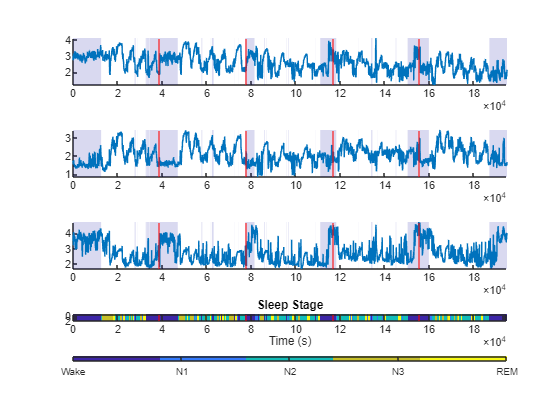

totalTime = linspace(0, length(totalBlockedData)*blockTime, length(totalBlockedData));

isWake = totalAnnotatedSleepStages == 1;

% Find start and end indices of wake segments
d = diff([0 isWake 0]);
wakeStarts = find(d == 1);
wakeEnds   = find(d == -1) - 1;


figure()

for i = 1:numChannels
    ax = subplot(numChannels+1, 1, i);
    hold on

    % Y-limits (needed for patch height)
    ylims = [min(totalBlockedData(i,:)) max(totalBlockedData(i,:))];

    % Draw wake background patches
    for k = 1:numel(wakeStarts)
        xPatch = [ ...
            totalTime(wakeStarts(k)), ...
            totalTime(wakeEnds(k)), ...
            totalTime(wakeEnds(k)), ...
            totalTime(wakeStarts(k)) ];

        yPatch = [ylims(1) ylims(1) ylims(2) ylims(2)];

        patch(xPatch, yPatch, [0 0 0.6], ...
              'FaceAlpha', 0.15, ...
              'EdgeColor', 'none', ...
              'Parent', ax);
    end

    % Plot data on top
    plot(totalTime, totalBlockedData(i,:))

    % Vertical separators
    if(sliceData)
        xline([selNumBlocks*(1:numPatients-1)]*blockTime, '-r');
    else
        xline(cumsum(numDataBlocksPerPatient*blockTime), '-r');
    end
    
    set(gca, 'XLim', [0 totalTime(end)])
    hold off
end


subplot(numChannels+1, 1, numChannels+1);
imagesc(totalTime, [0,1], totalAnnotatedSleepStages);
colormap(parula(5));
if(sliceData)
    xline([selNumBlocks*(1:numPatients-1)]*blockTime, '-r');
else
    xline(cumsum(numDataBlocksPerPatient*blockTime), '-r');
end
xlabel('Time (s)');
title('Sleep Stage');
c = colorbar('southoutside');
stageLabels = {'Wake','N1','N2','N3','REM'};

% Match colorbar ticks to stage codes 
c.Ticks = unique(annotatedSleepStages);
c.TickLabels = stageLabels;

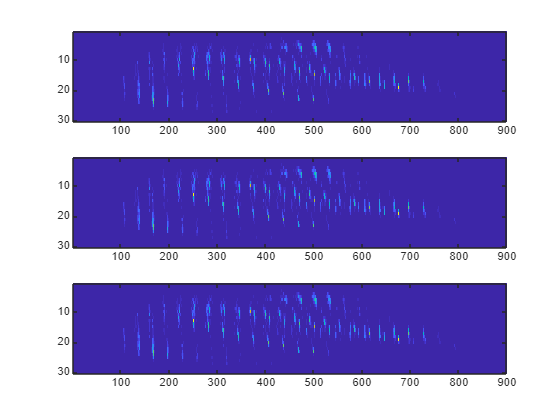


n = numChannels;
d = 30;
k = length(unique(annotatedSleepStages));

[~, mins, maxs] = NormalizeData(totalBlockedData);
[disc_seq,~] = discretize(totalBlockedData, d);

P3 = cell(n, 1);
for i = 1:n
    P3{i} = ProbabilityTensorGenerate(totalBlockedData, 3, d);
end

figure();
for i = 1:n
    subplot(n, 1, i);
    imagesc(mode_n_matricization(P3{i}, 1));
end

alpha = 0.05;
rho = 0.9;

cpd_options = {};

cpd_options.maxIter = 2500;
cpd_options.tol = 1e-16;
cpd_options.epsilon = 1/10;
cpd_options.ConvergeVars = false;

[T_hat, O_hats, pi_hat, cpd_output] = multivariate_coupled_cpd_2(P3, k, d, n, alpha, rho, cpd_options);


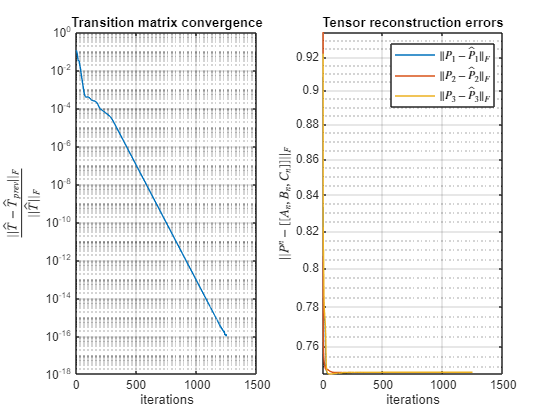

figure()
subplot(1, 2, 1);
semilogy(cpd_output.tconv);
title("Transition matrix convergence")
ylabel("$\frac{||\hat{T} - \hat{T}_{prev}||_F}{||\hat{T}||_F}$", "Interpreter","latex")
xlabel("iterations")
grid on;

subplot(1, 2, 2);
semilogy(cpd_output.rellrecerr')
title("Tensor reconstruction errors")
ylabel("$||P^n - [[A_n, B_n, C_n]]||_F$", "Interpreter","latex")
xlabel("iterations")
legendLabels = arrayfun(@(i) sprintf('$$\\|P_{%d} - \\hat{P}_{%d}\\|_F$$', i, i), 1:n, 'UniformOutput', false);
legend(legendLabels, 'Interpreter', 'latex');
grid on;

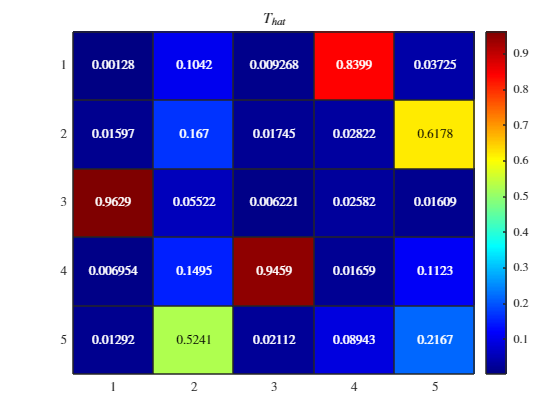

figure();
h = heatmap(T_hat, Colormap=jet());
h.Title = '$T_{hat}$';
h.Interpreter = 'latex';

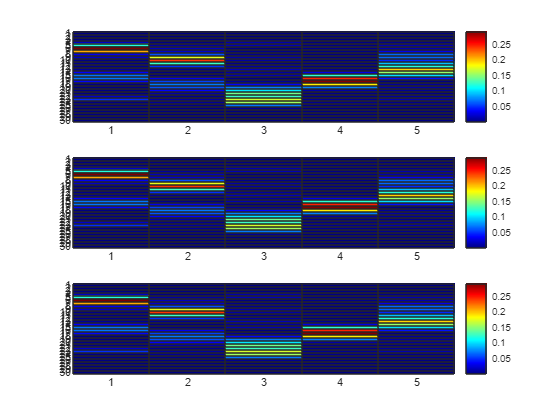


figure();
for i = 1:n
    subplot(n, 1, i);
    h = heatmap(O_hats{i}, Colormap=jet());
end

m = length(totalAnnotatedSleepStages);

% Apply Viterbi Algorithm
[viterbiPath, delta] = multivariate_viterbi_algorithm(disc_seq(:, 1:m), T_hat, O_hats, pi_hat, 0.5, 0);

% Remove permutation ambiguity by matching with true Viterbi path; the
% annotated sleep stages.
allperms = perms(1:k);

for ix=1:size(allperms,1)
    out_stages=permute_stages(viterbiPath, allperms(ix,:));
    score_vi(ix)=numel(find(out_stages==totalAnnotatedSleepStages(1:m)))/m;
end 

[msc,idx]=max(score_vi); % this finds the permutations with the best score and saves the index of the best permutation in idx.


% Permute the Viterbi path and HMM matrices according to the best fit.
viterbiPath = permute_stages(viterbiPath, allperms(idx,:));

T_hat = T_hat(allperms(idx,:), allperms(idx,:));

for i = 1:n
    O_hat = O_hats{i};
    O_hats{i} = O_hat(:, allperms(idx,:));
end

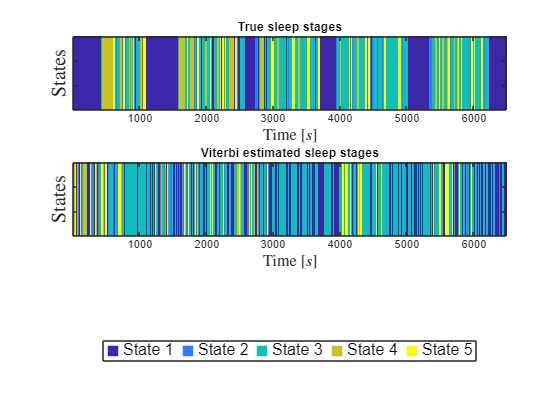



% Plot result

figure();

cmap = [0,0,0; parula(k)];
colormap(cmap);

subplot(3, 1, 1);
imagesc(1:m, [0 1], totalAnnotatedSleepStages(1:m)+1);
clim([1 k+1]);
ylabel("States", "Interpreter", "latex","FontSize",15);
set(gca,'YTickLabel',[]);
xlabel("Time [$s$]", "Interpreter", "latex","FontSize",12);
title("True sleep stages")


subplot(3, 1, 2);
imagesc(1:m, [0 1], viterbiPath+1);
clim([1 k+1]);
ylabel("States", "Interpreter", "latex","FontSize",15);
set(gca,'YTickLabel',[]);
xlabel("Time [$s$]", "Interpreter", "latex","FontSize",12);
title("Viterbi estimated sleep stages")

% --- Add legend as an invisible axes at the bottom ---
legend_ax = subplot(3, 1, 3);
axis off;  % Hide this subplot

% Create dummy handles for legend colors
hold on;
legendHandles = gobjects(k,1);
for i = 1:k
    legendHandles(i) = plot(nan, nan, 's', ...
        'MarkerFaceColor', cmap(i+1,:), ...
        'MarkerEdgeColor', cmap(i+1,:), ...
        'MarkerSize', 10);
end

legend(legendHandles, arrayfun(@(x) sprintf('State %d', x), 1:k, 'UniformOutput', false), ...
       'Orientation', 'horizontal', ...
       'Location', 'southoutside', ... 
       'FontSize', 12);

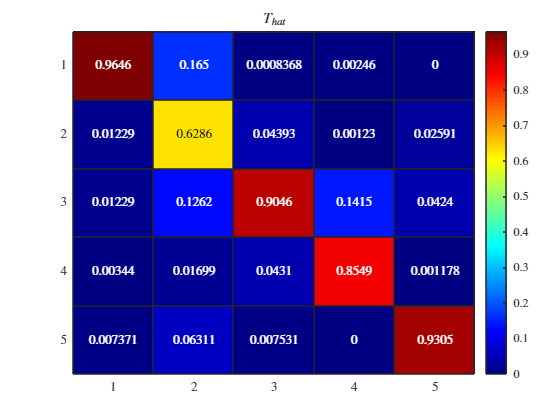




T_True = zeros(k,k);
O_True = cell(n, 1);

for i = 1:(m-1)
    z = zeros(k, k);
    z(totalAnnotatedSleepStages(i), totalAnnotatedSleepStages(i+1)) = 1;
    T_True = T_True + z;
end

T_True = Stochasticize(T_True);

for i = 1:n
    [T_true_temp, O_true_temp] = hmmestimate(disc_seq(i, 1:m), totalAnnotatedSleepStages(1:m), 'Symbols',1:d);
    O_True{i} = O_true_temp';
end

figure();
h = heatmap(T_True, Colormap=jet());
h.Title = '$T_{hat}$';
h.Interpreter = 'latex';

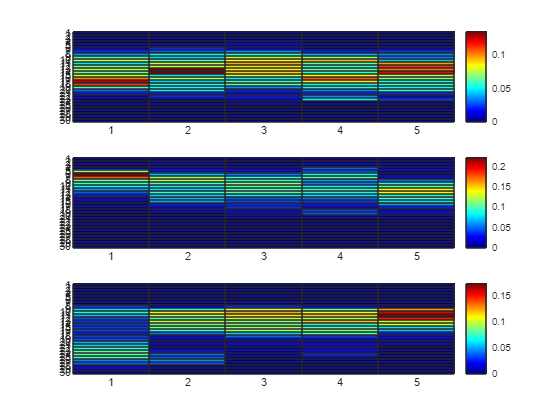



figure();
for i = 1:n
    subplot(n, 1, i);
    h = heatmap(O_True{i}, Colormap=jet());
end